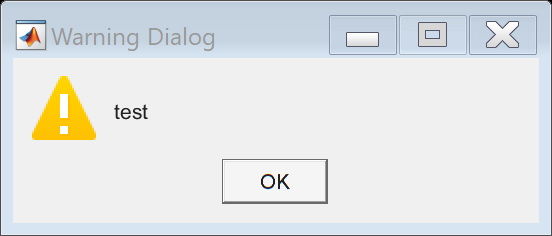

% Define parameters
Ma = 11; % Mach number
AoA_deg = 0:1:15; % Angle of Attack range in degrees
AoA_rad = AoA_deg * pi / 180; % Convert to radians

% Calculate C_L values
%% "Newtonian Impact Theory" 
C_L_Newtonian = 2 * sind(AoA_deg).^2;
%% "Thin Airfoil Theory" or "Linearized Supersonic Flow Theory"
C_L_Thin_Airfoil_Theory = 4 * AoA_rad ./ sqrt(Ma^2 - 1);

% Plot both curves
figure;
plot(AoA_deg, C_L_Newtonian, 'b-', 'LineWidth', 1.5); % Newtonian Theory
hold on;
plot(AoA_deg, C_L_Thin_Airfoil_Theory, 'r--', 'LineWidth', 1.5); % Thin Airfoil Theory

% Add labels and legend
xlabel('Angle of Attack (degrees)');
ylabel('Lift Coefficient, C_L');
title('Lift Coefficient (C_L) vs. Angle of Attack');
legend('Newtonian Theory', 'Thin Airfoil Theory');
grid on;
hold off;

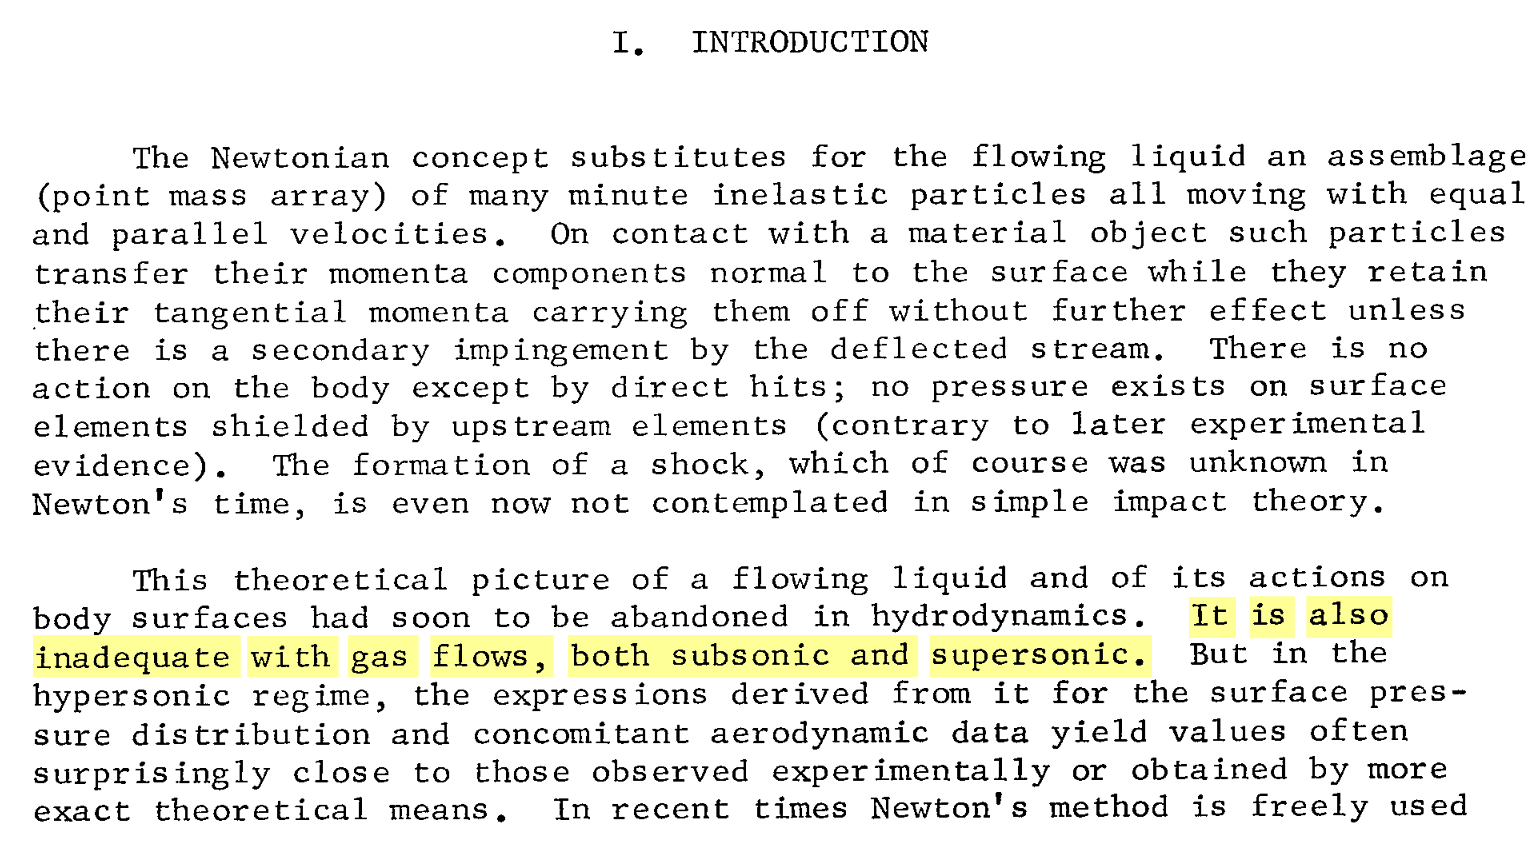

[https://ntrs.nasa.gov/api/citations/19660012440/downloads/19660012440.pdf]

# **=> For Supersonic Flow Newtonian Theory is not relevant**

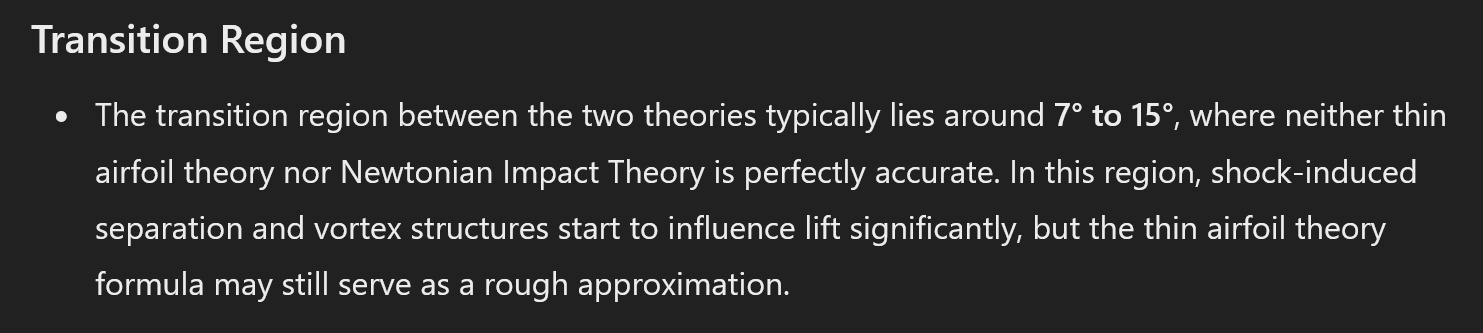

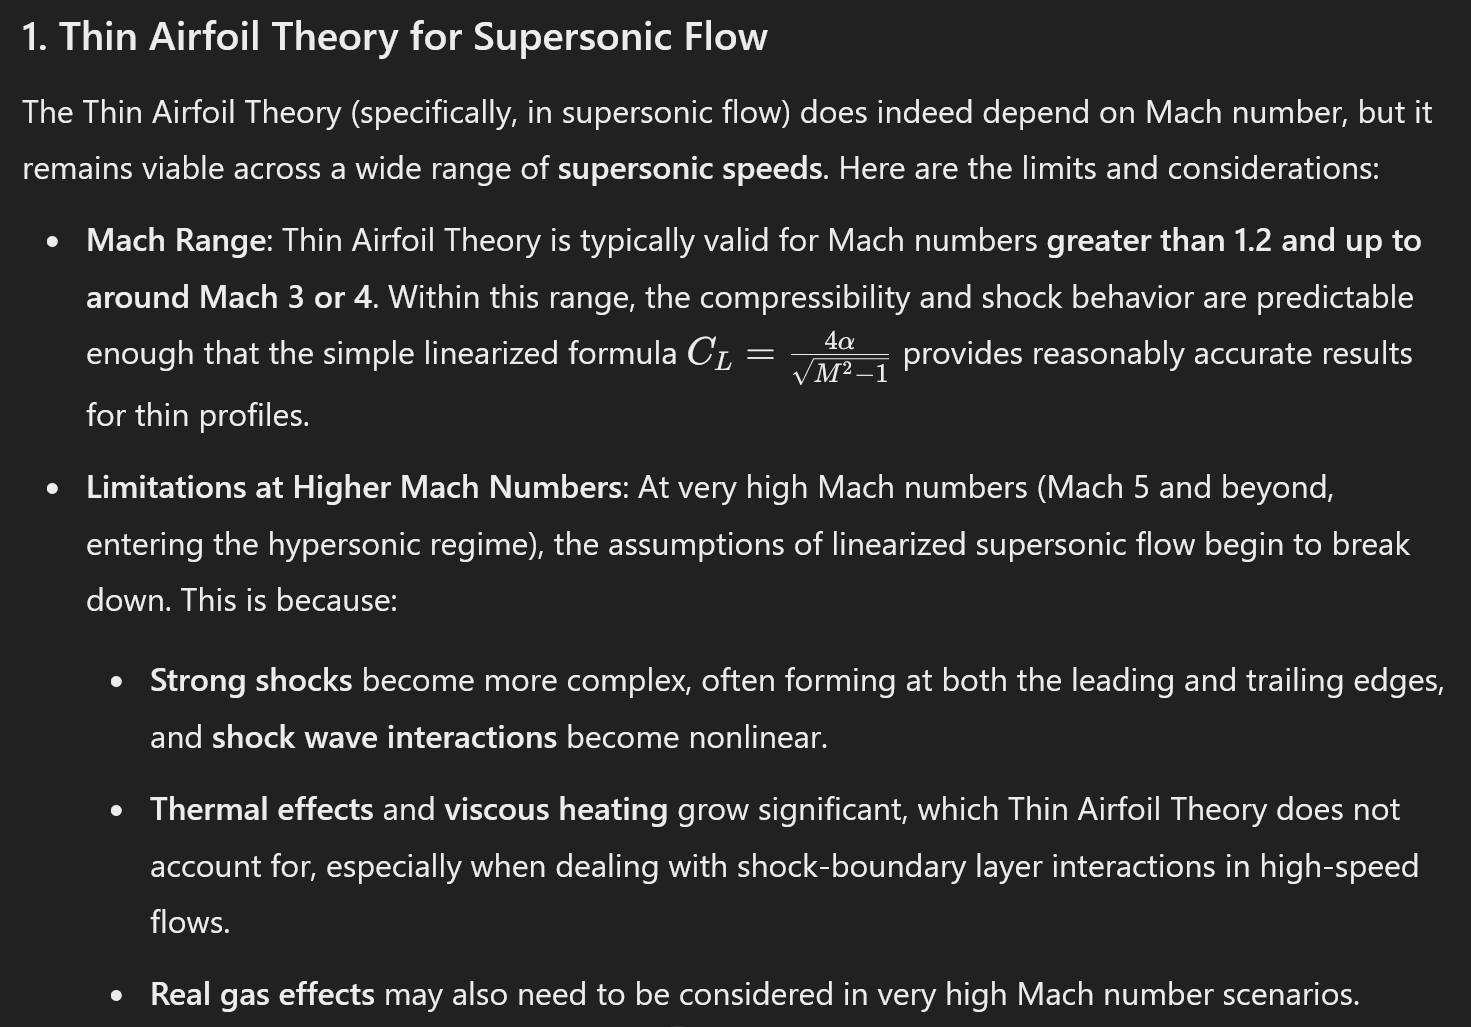

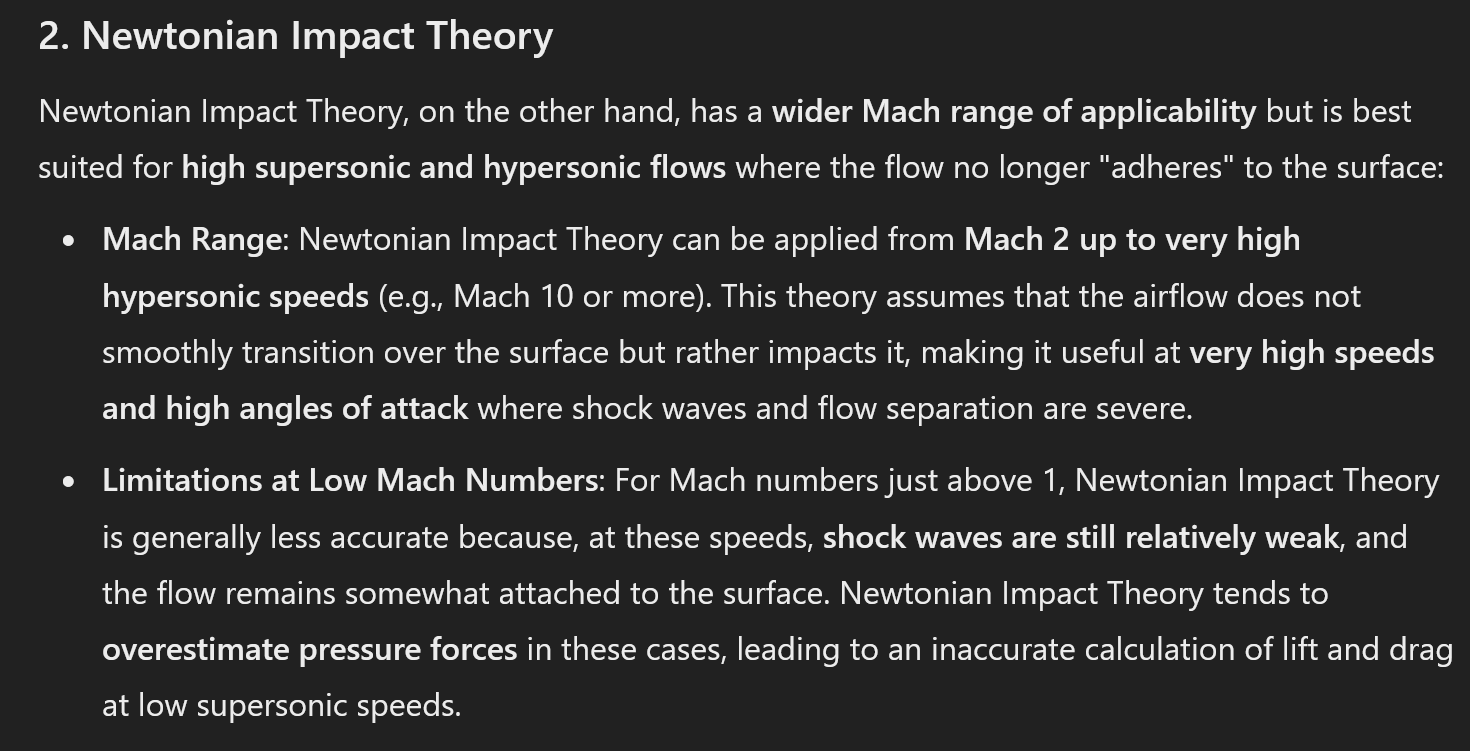

[ChatGPT]

- *C: According to calcs it is more like the pressure forces are being underestimated compared to the Thin Airfoil Theory*

- *C: At Ma=12 both theories are intersecting at ~10deg AoA*